clear; clc; close all;
cam = webcam();
im = snapshot(cam);
frameSize = size(im);
videoPlayer = vision.VideoPlayer('Position',[100 100 [frameSize(2), frameSize(1)+30]]);
runLoop = true;
s = serialport('COM3', 115200);
configureTerminator(s, "LF");
suma1 = 0;
suma0 = 0;

while runLoop
    videoFrame = snapshot(cam);
    %A= videoFrame;
    [bit,finalFrame,lines] = BrazoNaranja(videoFrame);
    %imshow(finalFrame)
    bit;
    if bit == 1
        suma1 = suma1 + 1;
        if suma1 == 5
            write(s, 1, 'int8')
            suma1=0;
        end
    elseif bit == 0
        suma0 = suma0 + 1;
        if suma0 == 5
            write(s, 0, 'int8')
            suma0 =0;
        end

    end
    step(videoPlayer,finalFrame);
    runLoop = isOpen(videoPlayer);
end

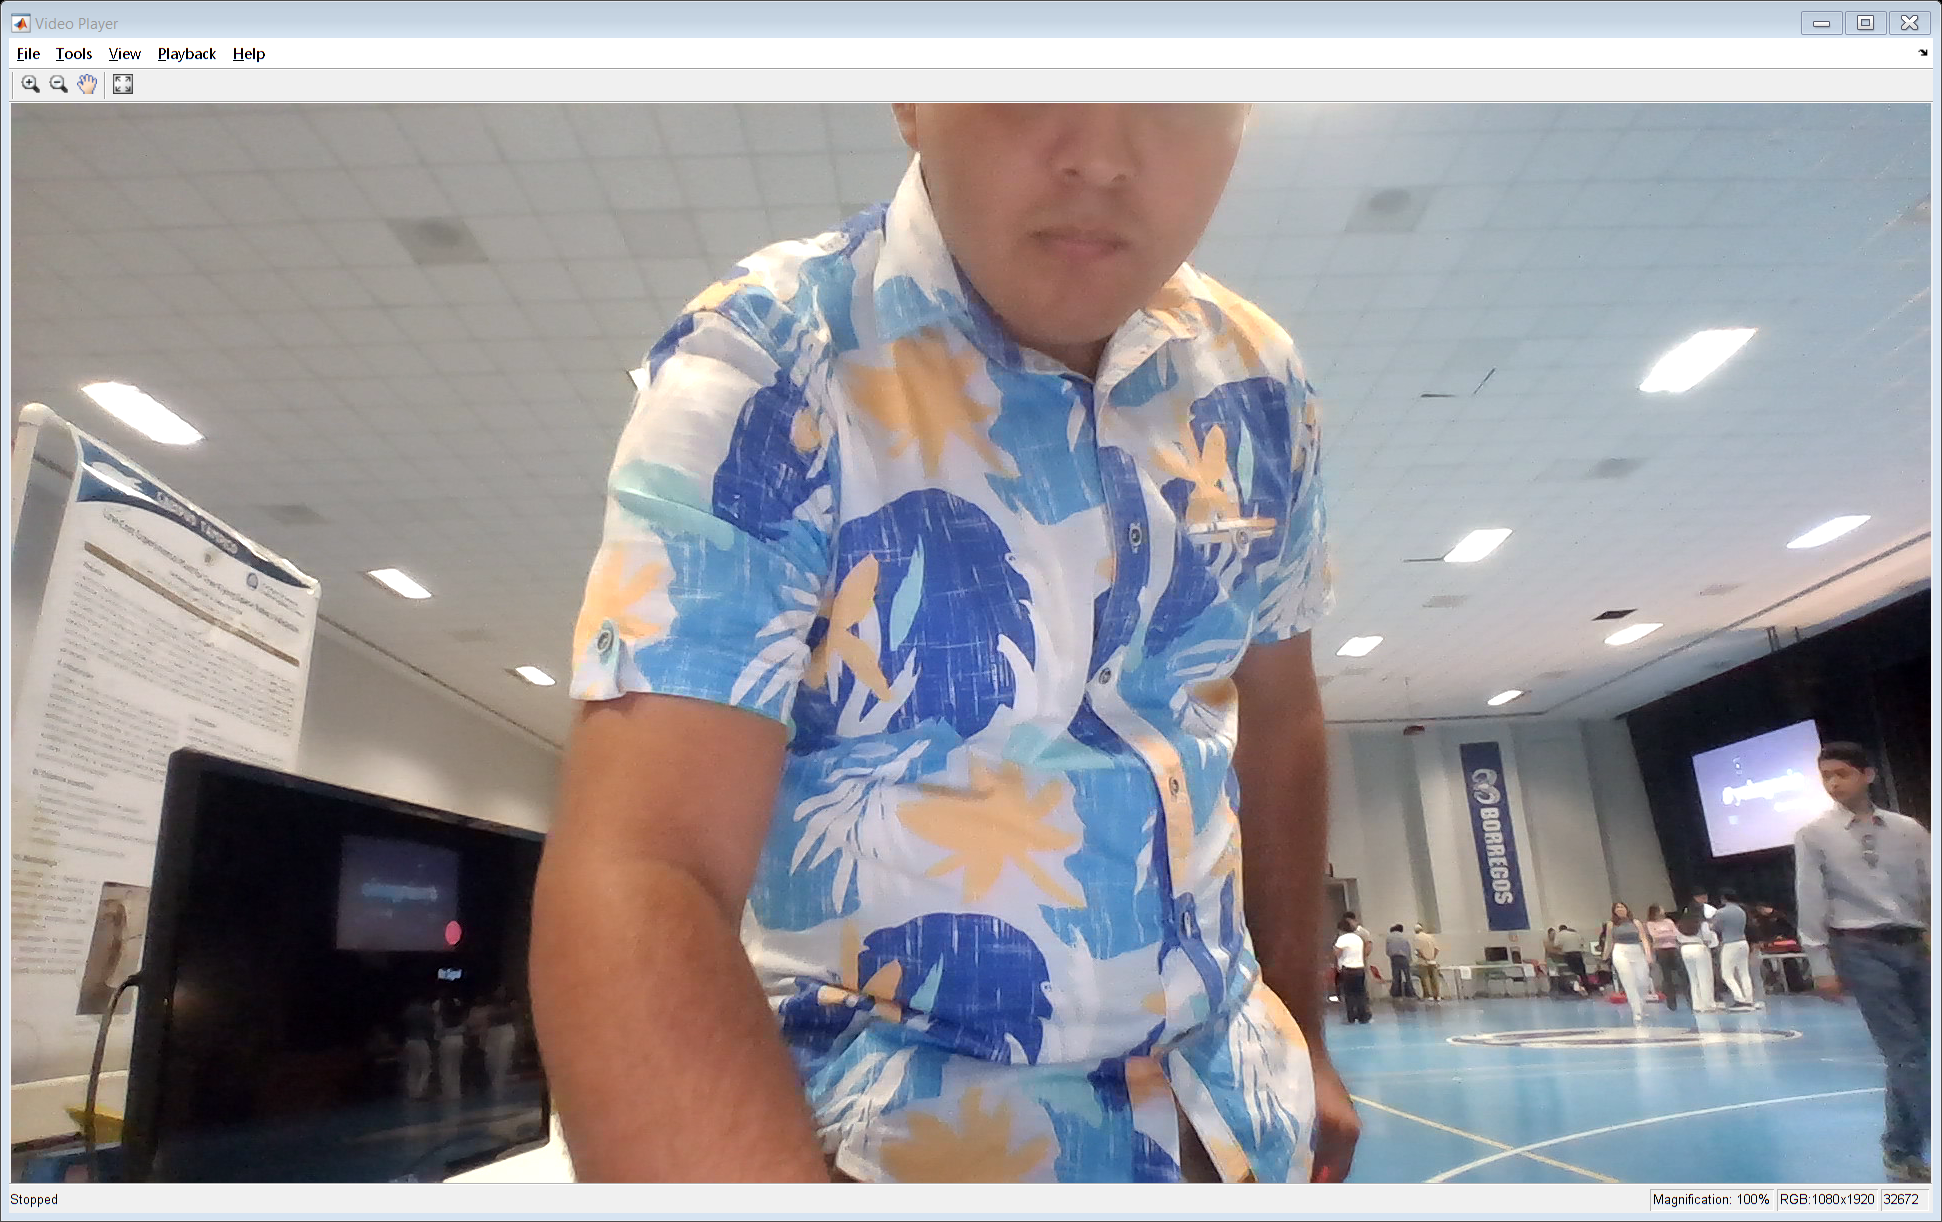

clear cam;
release(videoPlayer);

clear s;